clc; clear; close all;

load('EASPSA_NGA_West2_ASK14_Extension.mat');  % this data is new.

%%%%%%%%%%% This data relevant to those used in the BA19 %%%%%%%%%%%%

% df = df(df.EarthquakeMagnitude>3.0 & df.ClstD_km_<30,:);

 df = rmmissing(df);

%  writetable(df,'D:\UC_Berkeley_study\New_Approach_for_GMPE\Program\data_\EASPSA_NGA_West2_ASK14_Extension.csv','Delimiter',',','QuoteStrings',true);

 VarNames = df.Properties.VariableNames;
 
 f_eas_hz_loc = VarNames(contains(VarNames,' Hz'));
 
 f_eas_hz = split(f_eas_hz_loc); 
 
 f_eas_hz = str2double(f_eas_hz(:,:,1));
 
% Consider the usable frequency range
 eas_array_flatfile = df(:, f_eas_hz_loc); % eas amplitude 301 values. 

% this is data array of useable eas amplitude. 
 eas_array_useable = table2array(eas_array_flatfile);

% frequencies range used in the BA19.

  freq_array = Coeffs_Giving(1, 5, 5, 5, 7);

%  [C, ia, ib] = intersect(f_eas_hz, freq);
%  
%   eas_array = eas_array_useable(:, ia);

## Step - 2: Set up model

fc = 1

ip = 1

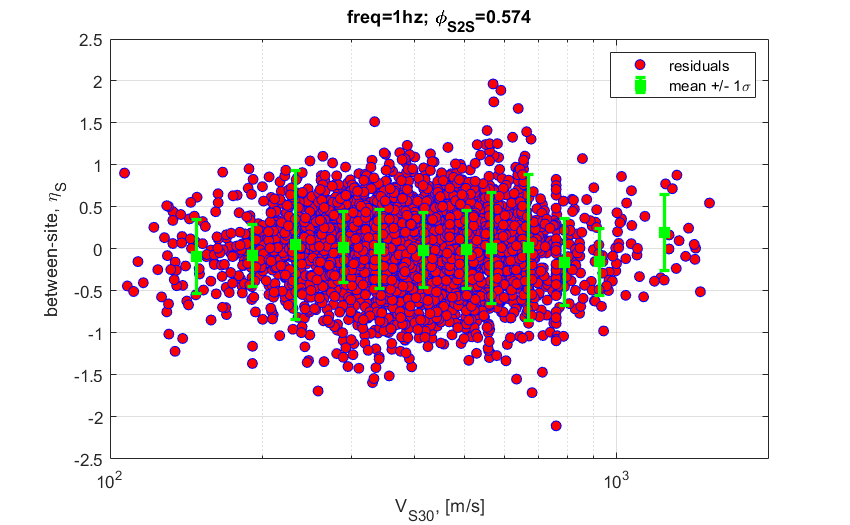

  
   ck_array = [];
 
   freg = [1	1.2022641	1.513561	1.698244	1.9952621	2.5118863	3.019952	5.011872	10	19.952621];
    
   b8a = [2.7385	2.7627	2.7075	2.6456	2.5200	2.2708	2.0279	1.4220	0.8540	0.2632];
    
   b8b = [-0.2886	-0.2891	-0.2825	-0.2762	-0.2642	-0.2411	-0.2190	-0.1632	-0.1075	-0.0499];

   b8 = [-0.8721	-0.8539	-0.8262	-0.8101	-0.7851	-0.7453	-0.7117	-0.6199	-0.4908	-0.3609];

%  [~, id] = min(abs(f_eas_hz - 1));
%  
%  f_reg = f_eas_hz(id);
 
    for fc = freg(1)
    
      fc
      ip = find(freg==fc)
      
      EQID = df.EQID;
      
      STAID = df.StationSequenceNumber;
      
      mag = df.EarthquakeMagnitude;
      
      rrup = df.ClstD_km_;
      
      Vs30 = df.Vs30_m_s_SelectedForAnalysis;
      
      Ztor = df.DepthToTopOfFaultRuptureModel;
      
      it = find(f_eas_hz == fc); 
    
  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    
       
       [freq, a_6, fM2Lmag, fSmag, fNS, fgeo, fSite, fc7b, delta_ZTOR] = Coeffs_Giving(fc,mag,rrup,Vs30,Ztor);
       
       ydata = eas_array_useable(:,it);
       
       fm1 = (mag - 6);
       fm2 = (8.5 - mag).^2;
       fD1 = log(rrup + 5*exp(0.4.*(mag-6)));
       fD2 = (mag - 6).*log(rrup + 5*exp(0.4.*(mag-6)));
       fD3 = rrup;
       fZ = min(Ztor/20,1);
       fS1 =  log(Vs30);
       fS2 =  log(Vs30).^2;
       fS =  b8a(ip)*log(Vs30) + b8b(ip)*log(Vs30).^2;
  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%     
        Res = log(ydata) - a_6*rrup;
         
        tb = table(Res, EQID, STAID, fm1,fm2,fD1,fD2,fS1,fS2,fZ, 'VariableNames',...
            {'Res','EQID','STAID','fm1','fm2','fD1','fD2','fS1','fS2','fZ'});
        
        lme = fitlme(tb,'Res ~ 1 + fm1 + fm2 + fD1 + fD2 +fS1+fS2 + fZ + (1|EQID) + (1|STAID)'); 
        
        ck = fixedEffects(lme); 
        
        [random, Bnames] = randomEffects(lme); 
    
        dBe = random(ismember(Bnames.Group,'EQID'));
    
        dS2S = random(ismember(Bnames.Group,'STAID'));

        Wes = residuals(lme);  
        
        tau = std(dBe(abs(dBe) <= 3.75*std(dBe)));
        
        phiSS = std(Wes(abs(Wes) <= 4*std(Wes)));

        ck_array = [ck_array [ck(end-1); ck(end-2)]];
      
    
           
        [~, ia] = unique(EQID);
        
        [~, ib] = unique(STAID);
        
    
        idg = discretize(Vs30(ib),[50 180 200 260 320 360 490 520 630 760 860 1000 2500]);
        meanfunc = @(x, y)[exp(mean(log(x))) mean(y) std(y)];
        outdata = splitapply(meanfunc,Vs30(ib),dS2S,idg);
        
        fig=figure('Position',[30 30 680 420]);
        s=semilogx(Vs30(ib), dS2S,'bo','MarkerFaceColor','r'); hold on;
        e= errorbar(outdata(:,1),outdata(:,2),outdata(:,3),'grsq','MarkerFaceColor','gr'); e.LineWidth = 2;
        legend('residuals','mean +/- 1\sigma');
        xlabel('V_{S30}, [m/s]'); 
        ylabel('between-site, \eta_S'); grid on;
        axis([100 2000 -2.5 2.5]); 
        title(['freq=',num2str(fc),'hz; \phi_{S2S}=',num2str(round(std(dS2S),3))]);
        
        fig_name = strcat('f_',num2str(fc),'hz_squ.jpg');
        % saveas (fig, ['D:\UC_Berkeley_study\New_Approach_for_GMPE\Program\figures_stage2\',fig_name]);  
        
    end 

    
%     figure;
%     subplot(3,1,1)
%     plot(mag(ia), dBe,'bo','MarkerFaceColor','r');
%     xlabel('M'); grid on;
%     ylabel('\eta_e');
%     axis([3 8 -3.5 3.5]);
%     
%     subplot(3,1,2)
%     semilogx(Vs30(ib), dS2S,'bo','MarkerFaceColor','r');
%     xlabel('V_{S30}, [m/s]'); 
%     ylabel('\eta_S'); grid on;
%     axis([100 2000 -2.5 2.5]); 
%     
%     subplot(3,1,3)
%     semilogx(rrup,Wes,'bo','MarkerFaceColor','r');
%     xlabel('R_{rup}, [km]');
%     ylabel('\delta W_{es}'); grid on;
%     axis([0.1 500 -3.5 3.5]);
